# Modelling - Decision Tree & K-Nearest Neighbor

## 0) Setup

Clear workspace, load datasets with different preprocessings and convert to matrices

clear; clc; % Clear workspace
rng(1) % set seed for reproducability

% Load baseline train and test data
train = readtable('train.csv');
test = readtable('test.csv');

train = train{:,:};  % Convert to matrix
test = test{:,:};

X_train = train(:, 2:end); % Split into target and features 
y_train = train(:, 1);
X_test = test(:, 2:end);
y_test = test(:, 1);


% Load oversampled train data
X_train_SMOTE = readtable('X_train_SMOTE.csv');
y_train_SMOTE = readtable('y_train_SMOTE.csv');

X_train_SMOTE = X_train_SMOTE{:,:};
y_train_SMOTE = y_train_SMOTE{:,:};

% Load PCA X_train and X_test data
X_train_PCA = readtable('X_train_PCA.csv', 'HeaderLines', 1);
X_test_PCA = readtable('X_test_PCA.csv', 'HeaderLines', 1);

X_train_PCA = X_train_PCA{:,:};
X_test_PCA = X_test_PCA{:,:};

% Load SMOTE PCA X_train and X_test data
X_train_SMOTE_PCA = readtable('X_train_SMOTE_PCA.csv', 'HeaderLines', 1);
X_test_SMOTE_PCA = readtable('X_test_SMOTE_PCA.csv', 'HeaderLines', 1);

X_train_SMOTE_PCA = X_train_SMOTE_PCA{:,:};
X_test_SMOTE_PCA = X_test_SMOTE_PCA{:,:};

## 1) Train / Test Baseline Models

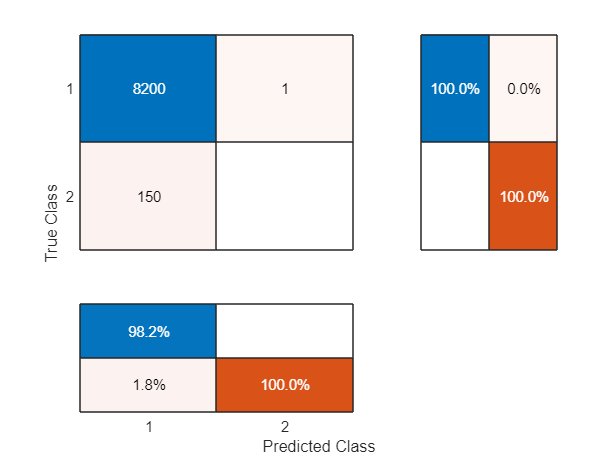

accuracy = 0.9819

precision = 0

recall = 0

specificity = 0.9999

fb = 0

% 1a) Baseline Decision Tree with default parameters
% Train
dt_base = fitctree(X_train, y_train, 'Reproducible', 1, 'MaxNumSplits', 10, 'MinLeafSize', 1);
% Evaluate baseline tree
test_model(dt_base, X_test, y_test)

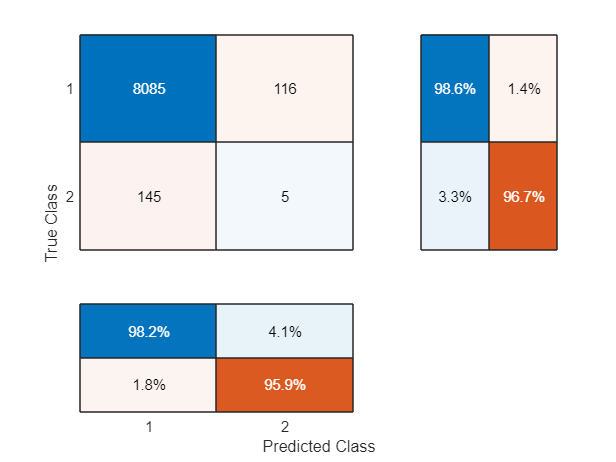

accuracy = 0.9687

precision = 0.0413

recall = 0.0333

specificity = 0.9859

fb = 0.0369

% 1b) Baseline KNN
% Train
knn_base = fitcknn(X_train, y_train, 'Standardize', 1, 'NumNeighbors', 1, 'Distance', 'euclidean', 'DistanceWeight', 'equal'); 
% Evaluate baseline knn
test_model(knn_base, X_test, y_test)

## 2) Hyperparameter Tuning Models (CV = k-fold, loss = accuracy)

% CV SPLITS: Define a random partition of data (fixes the train and validation set)
[nrow, ncol] = size(X_train);
c = cvpartition(nrow,'KFold', 20);

% DECISION TREE: Define vars and range
MaxNumSplit = optimizableVariable('MaxNumSplit',[1, 30],'Type','integer');  % default: 10
MinLeafSize = optimizableVariable('MinLeafSize', [1, 30], 'Type', 'integer');  % default: 1

ParamsDT = [MaxNumSplit, MinLeafSize];

% KNN: Define vars and range
n = optimizableVariable('n',[1,20],'Type','integer'); % defualt: 1
dst = optimizableVariable('dst', {'euclidean', 'cosine', 'correlation'},'Type','categorical'); % default: euclidean
dstWeight = optimizableVariable('dstWeight', {'equal','inverse', 'squaredinverse'},'Type','categorical');  % default: equal

ParamsKNN = [n; dst; dstWeight];

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.014908 |      1.1448 |    0.014908 |    0.014908 |           22 |            3 |
|    2 | Best   |    0.014759 |     0.56075 |    0.014759 |     0.01476 |            3 |           30 |
|    3 | Accept |    0.014849 |     0.64316 |    0.014759 |    0.014759 |            6 |            2 |
|    4 | Accept |    0.014759 |     0.73856 |    0.014759 |    0.014759 |           12 |           29 |
|    5 | Accept |    0.014759 |     0.77662 |    0.014759 |    0.014759 |           29 |           14 |
|    6 | Accept |    0.014789 |      0.8482 |    0.014759 |    0

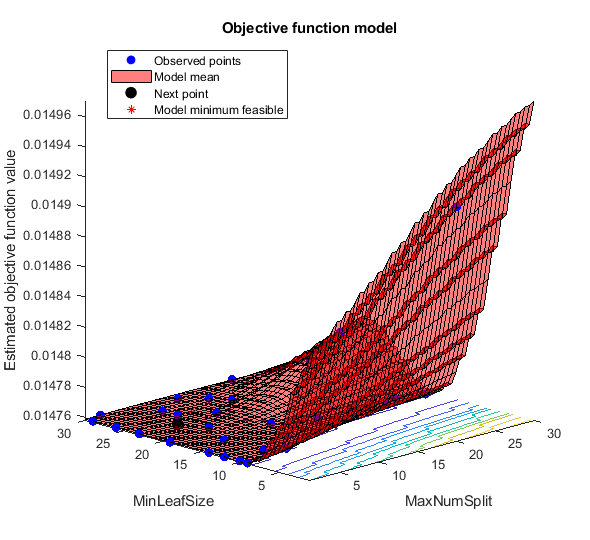

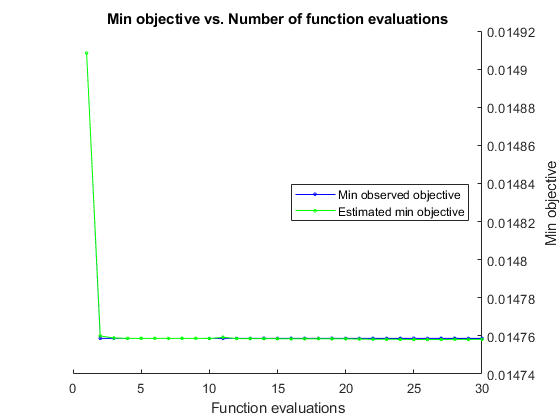


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 43.3565 seconds
Total objective function evaluation time: 18.8282

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

         3             30     

Observed objective function value = 0.014759
Estimated objective function value = 0.014759
Function evaluation time = 0.56075

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

         1             10     

Estimated objective function value = 0.014758
Estimated function evaluation time = 0.37216



% 2a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = accuracy)
% 2a-i) Define loss function
loss = @(params)kfoldLoss(fitctree(X_train, y_train, 'CVPartition', c, 'Reproducible', 1,...
                                     'MaxNumSplits',params.MaxNumSplit, ...
                                     'MinLeafSize',params.MinLeafSize));

% 2a-ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

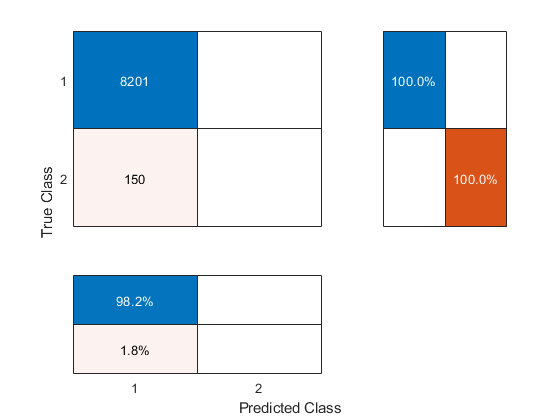

accuracy = 0.9820

precision = NaN

recall = 0

specificity = 1

fb = 0

% 2a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1,...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 2a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |    dstWeight |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |    0.014938 |      5.1302 |    0.014938 |    0.014938 |            5 |    euclidean |        equal |
|    2 | Best   |    0.014759 |      4.8907 |    0.014759 |    0.014849 |           11 |       cosine |        equal |
|    3 | Accept |    0.016226 |      4.9092 |    0.014759 |    0.015307 |           18 |       cosine |      inverse |
|    4 | Accept |    0.028589 |      4.8996 |    0.014759 |    0.014783 |            1 |       cosine |      inverse |
|    5 | Accept |    0.024937 |      4.8863 |   

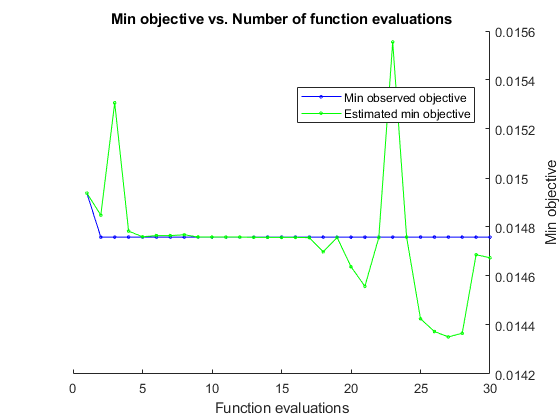


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 160.8737 seconds
Total objective function evaluation time: 148.0736

Best observed feasible point:
    n      dst      dstWeight
    __    ______    _________

    11    cosine      equal  

Observed objective function value = 0.014759
Estimated objective function value = 0.014769
Function evaluation time = 4.8907

Best estimated feasible point (according to models):
    n       dst       dstWeight
    _    _________    _________

    7    euclidean      equal  

Estimated objective function value = 0.014674
Estimated function evaluation time = 4.9321



% 2b) KNN: Bayesian Optimization (CV = k-fold, loss = accuracy)
% 2b-i) Define loss function
loss = @(params)kfoldLoss(fitcknn(X_train, y_train, 'Standardize', 1, 'CVPartition', c, ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst), ...
            'DistanceWeight',char(params.dstWeight)));

% 2b-ii) Optimize model
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

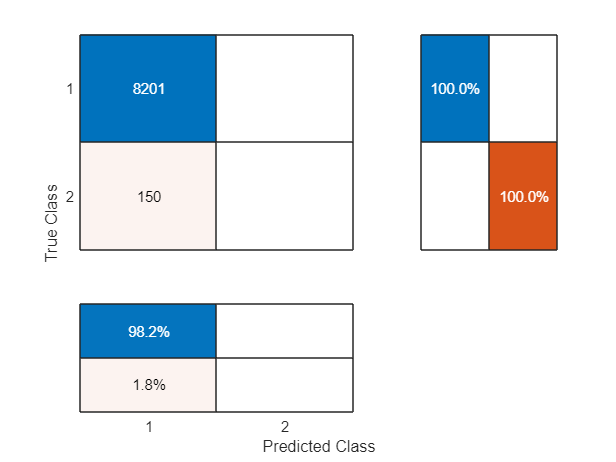

accuracy = 0.9820

precision = NaN

recall = 0

specificity = 1

fb = 0

% 2b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst), ...
    'DistanceWeight',char(z.dstWeight));

% 2b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

## 3) Hyperparameter Tuning Models (CV = k-fold, loss = f-beta)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |           1 |     0.54521 |           1 |           1 |            2 |           23 |
|    2 | Accept |           1 |     0.71391 |           1 |           1 |           28 |           11 |
|    3 | Accept |           1 |     0.52674 |           1 |           1 |            7 |           21 |
|    4 | Accept |           1 |     0.77927 |           1 |           1 |           21 |            3 |
|    5 | Accept |           1 |     0.82611 |           1 |           1 |           25 |           24 |
|    6 | Accept |           1 |      0.7027 |           1 |     

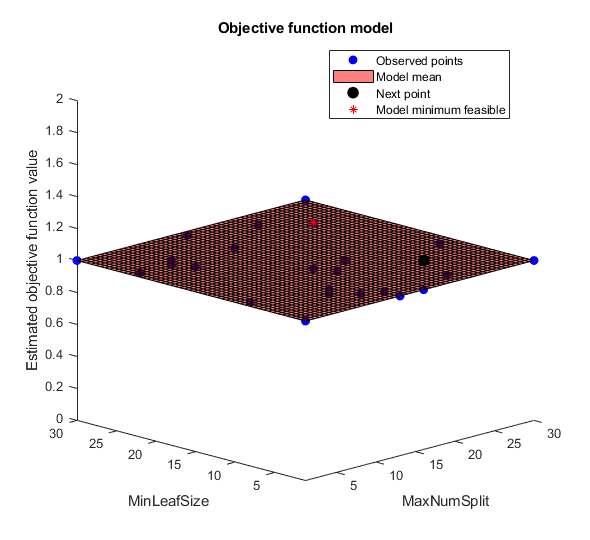

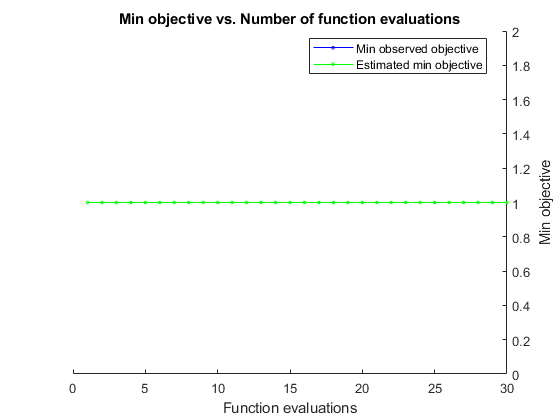


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 41.1052 seconds
Total objective function evaluation time: 20.6291

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

         2             23     

Observed objective function value = 1
Estimated objective function value = 1
Function evaluation time = 0.54521

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

         2             23     

Estimated objective function value = 1
Estimated function evaluation time = 0.48624



% 3a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = f-beta)
% 3a-i) Define loss function
loss = @(params)fb_loss_dt_cv(params,X_train,y_train, c); % see helper function

% 3a-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.9820

precision = NaN

recall = 0

specificity = 1

fb = 0


% 3a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1, ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 3a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |    dstWeight |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |           1 |      5.0115 |           1 |           1 |           18 |  correlation |        equal |
|    2 | Accept |           1 |      4.8711 |           1 |           1 |           10 |    euclidean |      inverse |
|    3 | Best   |      0.9636 |      4.7983 |      0.9636 |     0.97912 |            2 |       cosine | squaredinver |
|    4 | Accept |           1 |      5.0326 |      0.9636 |      0.9636 |           18 |    euclidean |      inverse |
|    5 | Best   |     0.96356 |      4.7589 |   

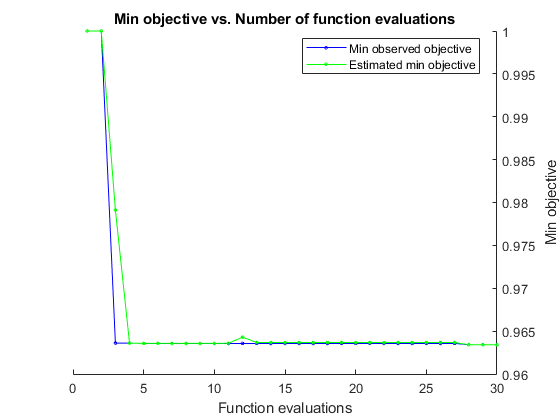


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 165.0415 seconds
Total objective function evaluation time: 153.645

Best observed feasible point:
    n        dst        dstWeight
    _    ___________    _________

    1    correlation     inverse 

Observed objective function value = 0.96341
Estimated objective function value = 0.96342
Function evaluation time = 5.5709

Best estimated feasible point (according to models):
    n        dst        dstWeight
    _    ___________    _________

    1    correlation     inverse 

Estimated objective function value = 0.96342
Estimated function evaluation time = 5.5484



% 3b) KNN: Bayesian Optimization (CV = k-fold, loss = f-beta)
% 3b-i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train,y_train, c); % see helper function

% 3b-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

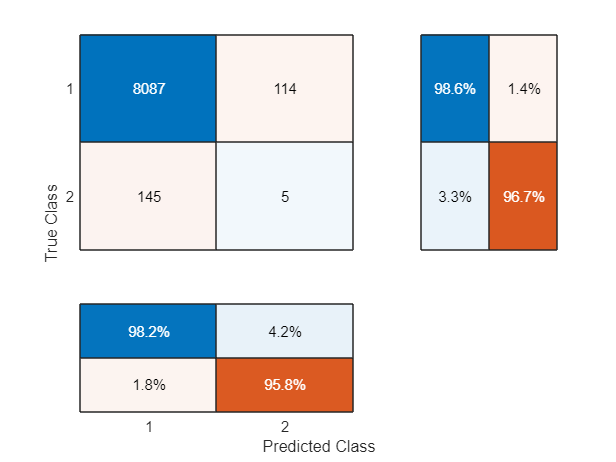

accuracy = 0.9690

precision = 0.0420

recall = 0.0333

specificity = 0.9861

fb = 0.0372


% 3b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst), ...
    'DistanceWeight',char(z.dstWeight));

% 3b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

## 4) Hyperparameter Tuning Models (CV = statify, loss = f-beta)

% CV SPLITS (Stratified)
c_strat = cvpartition(y_train,'KFold', 20, 'Stratify', true);

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |           1 |      0.9297 |           1 |           1 |           27 |           11 |
|    2 | Best   |     0.99606 |     0.84036 |     0.99606 |     0.99802 |           29 |            1 |
|    3 | Accept |           1 |     0.53999 |     0.99606 |     0.99606 |            6 |           20 |
|    4 | Accept |           1 |     0.74173 |     0.99606 |     0.99606 |           28 |           27 |
|    5 | Accept |           1 |     0.71402 |     0.99606 |     0.99606 |           20 |            8 |
|    6 | Accept |           1 |     0.72799 |     0.99606 |     

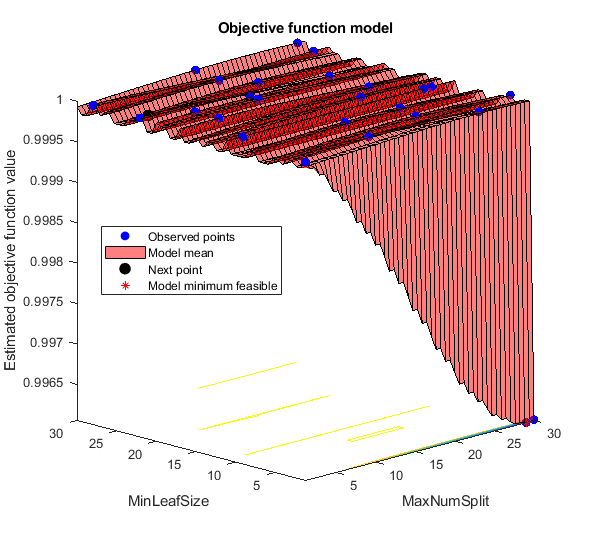

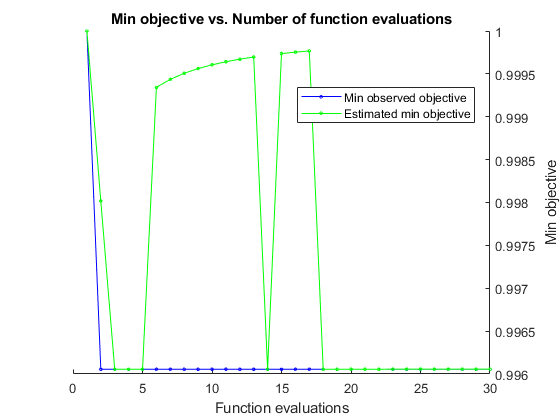


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 38.8303 seconds
Total objective function evaluation time: 22.9415

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

        29              1     

Observed objective function value = 0.99606
Estimated objective function value = 0.99606
Function evaluation time = 0.84036

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

        29              1     

Estimated objective function value = 0.99606
Estimated function evaluation time = 0.99972



% 4a) Decision Tree: Bayesian Optimization (CV = statify, loss = f-beta)
% 4a-i) Define loss function
loss = @(params)fb_loss_dt_cv(params,X_train,y_train, c_strat); % see helper function

% 4a-ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

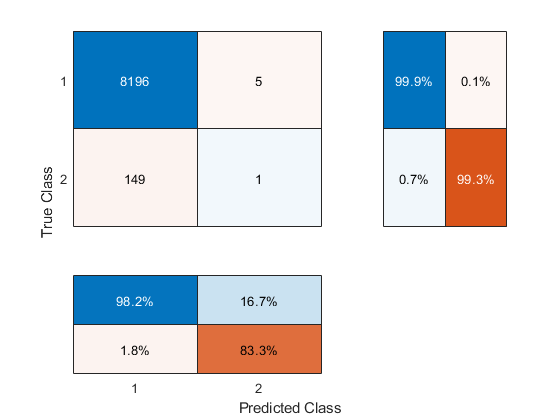

accuracy = 0.9816

precision = 0.1667

recall = 0.0067

specificity = 0.9994

fb = 0.0128


% 4a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1, ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 4a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

% 4b) KNN: Bayesian Optimization (CV = statify, loss = f-beta)
disp('***** Hyperparameter Tuning KNN (CV = statify, loss = f-beta) *****')

***** Hyperparameter Tuning KNN (CV = statify, loss = f-beta) *****



% 4b-i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train,y_train, c_strat) % see helper function

loss = function_handle with value:
    @(params)fb_loss_knn_cv(params,X_train,y_train,c_strat)


|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |    dstWeight |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |      0.9761 |      4.8516 |      0.9761 |      0.9761 |           19 |  correlation | squaredinver |
|    2 | Accept |           1 |       4.773 |      0.9761 |     0.97705 |           19 |       cosine |        equal |
|    3 | Best   |     0.97403 |      5.1083 |     0.97403 |      0.9746 |            4 |    euclidean | squaredinver |
|    4 | Accept |     0.97866 |      4.9006 |     0.97403 |     0.97476 |            5 |       cosine |      inverse |
|    5 | Accept |     0.99288 |      4.8865 |   

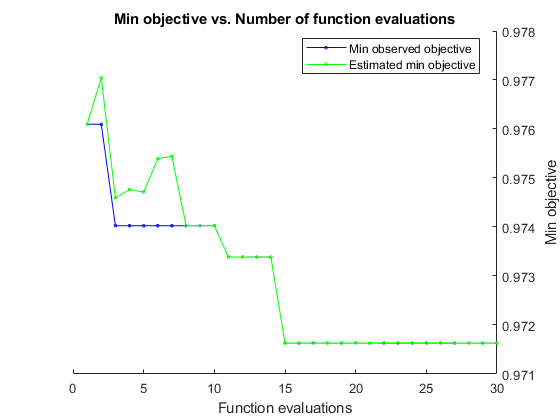


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 186.2336 seconds
Total objective function evaluation time: 172.1905

Best observed feasible point:
    n     dst        dstWeight   
    _    ______    ______________

    1    cosine    squaredinverse

Observed objective function value = 0.97163
Estimated objective function value = 0.97163
Function evaluation time = 4.4825

Best estimated feasible point (according to models):
    n     dst        dstWeight   
    _    ______    ______________

    1    cosine    squaredinverse

Estimated objective function value = 0.97163
Estimated function evaluation time = 5.5767




% 4b-ii) Optimize model
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

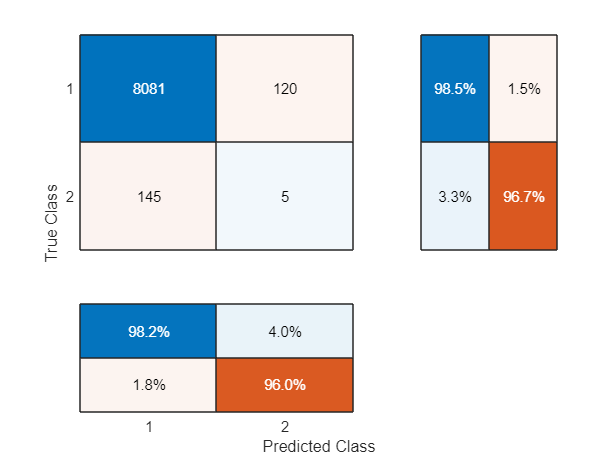

accuracy = 0.9683

precision = 0.0400

recall = 0.0333

specificity = 0.9854

fb = 0.0364


% 4b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst), ...
    'DistanceWeight',char(z.dstWeight));

% 4b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

## 5) Hyperparameter Tuning Models (CV = k-fold, loss = f-beta, SMOTE)

% CV SPLITS SMOTE:
[nrow, ncol] = size(X_train_SMOTE);
c_SMOTE = cvpartition(nrow,'KFold', 20);

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.12873 |     0.90092 |     0.12873 |     0.12873 |            2 |           23 |
|    2 | Best   |    0.087182 |      1.5862 |    0.087182 |    0.089252 |           28 |           11 |
|    3 | Accept |     0.11472 |      1.1436 |    0.087182 |    0.087944 |            7 |           21 |
|    4 | Accept |    0.088301 |       1.615 |    0.087182 |    0.087181 |           21 |            3 |
|    5 | Best   |     0.08716 |      1.6447 |     0.08716 |    0.087122 |           25 |           24 |
|    6 | Accept |     0.10012 |       1.976 |     0.08716 |    0

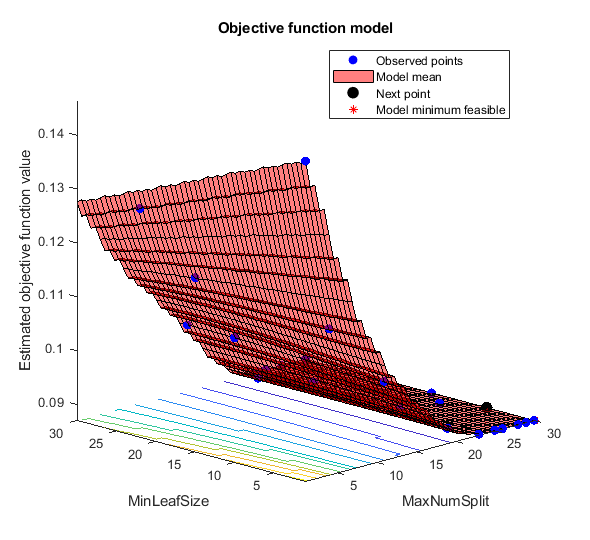

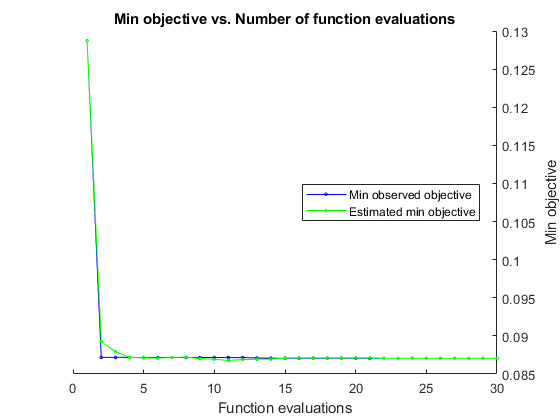


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 63.8799 seconds
Total objective function evaluation time: 46.347

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

        30              1     

Observed objective function value = 0.08707
Estimated objective function value = 0.087068
Function evaluation time = 1.6136

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

        29              1     

Estimated objective function value = 0.087072
Estimated function evaluation time = 1.6419



% 5a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = f-beta, SMOTE)
% 5a-i) Define loss function
loss = @(params)fb_loss_dt_cv(params,X_train_SMOTE,y_train_SMOTE, c_SMOTE); % see helper function

% 5a-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

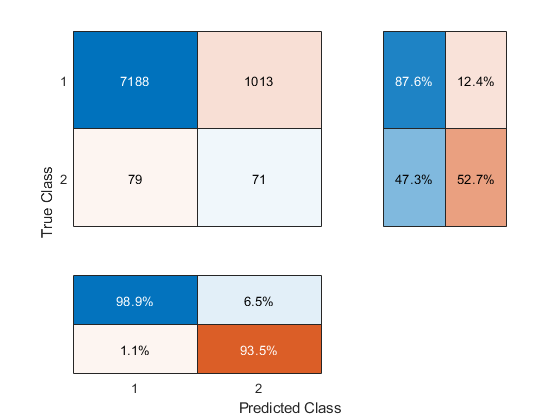

accuracy = 0.8692

precision = 0.0655

recall = 0.4733

specificity = 0.8765

fb = 0.1151


% 5a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train_SMOTE, y_train_SMOTE, 'Reproducible', 1, ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 5a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |    dstWeight |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |    0.019899 |       19.22 |    0.019899 |    0.019899 |           18 |  correlation |        equal |
|    2 | Best   |    0.014483 |      19.857 |    0.014483 |    0.014873 |           10 |    euclidean |      inverse |
|    3 | Accept |    0.015067 |      21.222 |    0.014483 |    0.014578 |            2 |       cosine | squaredinver |
|    4 | Accept |    0.017844 |      20.218 |    0.014483 |    0.016776 |           18 |    euclidean |      inverse |
|    5 | Accept |    0.015067 |      21.164 |   

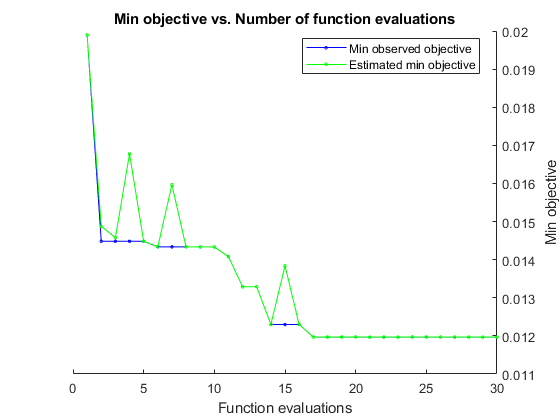


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 648.916 seconds
Total objective function evaluation time: 630.4924

Best observed feasible point:
    n       dst       dstWeight
    _    _________    _________

    4    euclidean     inverse 

Observed objective function value = 0.011969
Estimated objective function value = 0.011969
Function evaluation time = 20.2455

Best estimated feasible point (according to models):
    n       dst       dstWeight
    _    _________    _________

    4    euclidean     inverse 

Estimated objective function value = 0.011969
Estimated function evaluation time = 20.9478



% 5b) KNN: Bayesian Optimization (CV = k-fold, loss = f-beta, SMOTE)
% 5b-i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train_SMOTE, y_train_SMOTE, c_SMOTE); % see helper function

% 5b-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

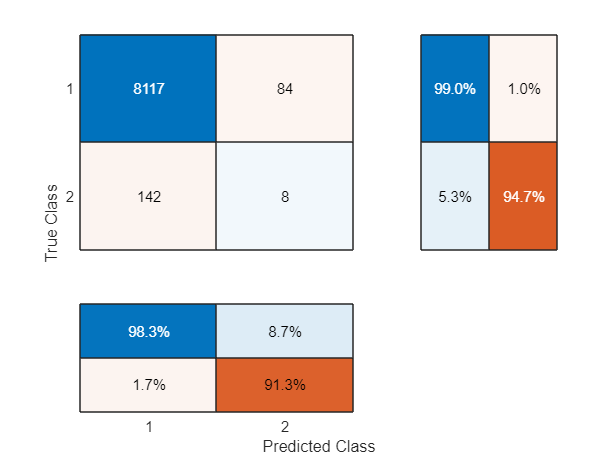

accuracy = 0.9729

precision = 0.0870

recall = 0.0533

specificity = 0.9898

fb = 0.0661


% 5b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train_SMOTE, y_train_SMOTE, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst), ...
    'DistanceWeight',char(z.dstWeight));

% 5b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

## 6) Hyperparameter Tuning Models (CV = k-fold, loss = accuracy, SMOTE)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.090335 |      1.7235 |    0.090335 |    0.090335 |           22 |           26 |
|    2 | Accept |    0.096032 |      1.6447 |    0.090335 |    0.090948 |           18 |            5 |
|    3 | Accept |     0.10626 |      1.5167 |    0.090335 |    0.091639 |           14 |           22 |
|    4 | Best   |    0.090107 |      1.6235 |    0.090107 |    0.090107 |           27 |           28 |
|    5 | Accept |    0.090137 |      1.6994 |    0.090107 |    0.090103 |           29 |            8 |
|    6 | Accept |     0.11896 |      1.3039 |    0.090107 |    0

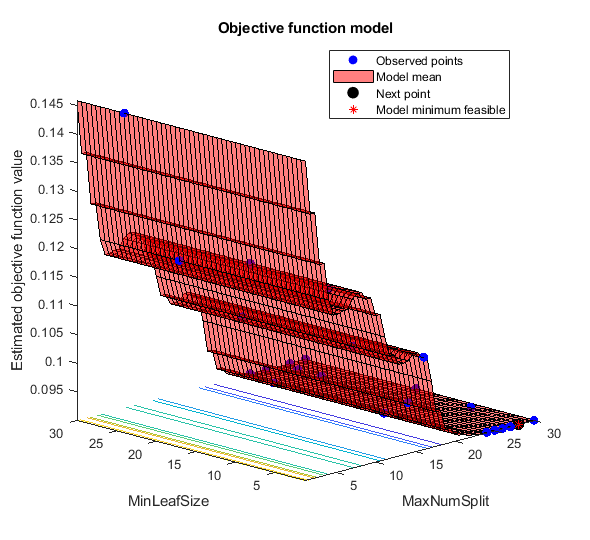

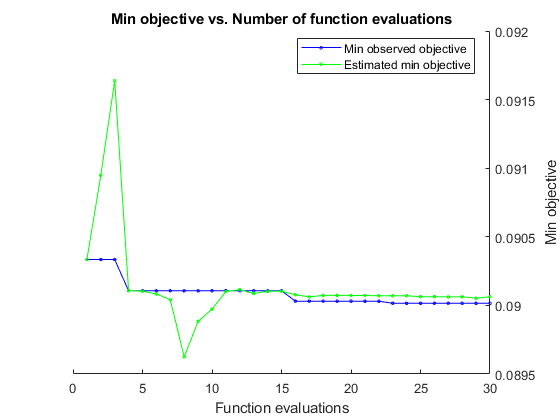


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 62.258 seconds
Total objective function evaluation time: 45.6436

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

        27              1     

Observed objective function value = 0.090015
Estimated objective function value = 0.090073
Function evaluation time = 1.5436

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

        26              1     

Estimated objective function value = 0.090063
Estimated function evaluation time = 1.5666



% 6a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = accuracy, SMOTE)
% 6a-i) Define loss function
loss = @(params)kfoldLoss(fitctree(X_train_SMOTE, y_train_SMOTE, 'CVPartition', c_SMOTE, 'Reproducible', 1,...
                                     'MaxNumSplits',params.MaxNumSplit, ...
                                     'MinLeafSize',params.MinLeafSize));

% 6a-ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.8692

precision = 0.0655

recall = 0.4733

specificity = 0.8765

fb = 0.1151

% 6a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train_SMOTE, y_train_SMOTE, 'Reproducible', 1,...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 6a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |    dstWeight |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |    0.014402 |      18.357 |    0.014402 |    0.014402 |            4 |       cosine | squaredinver |
|    2 | Best   |    0.014083 |      37.295 |    0.014083 |    0.014121 |            7 |       cosine |        equal |
|    3 | Accept |     0.01501 |      21.172 |    0.014083 |    0.014499 |            9 |       cosine | squaredinver |
|    4 | Best   |    0.013825 |      18.334 |    0.013825 |    0.014173 |           10 |       cosine |      inverse |
|    5 | Accept |    0.017168 |      19.631 |   

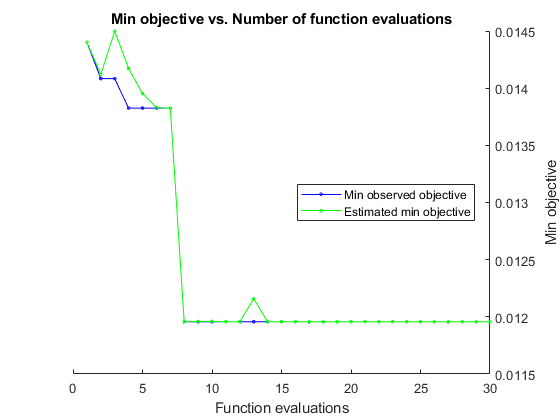


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 656.9176 seconds
Total objective function evaluation time: 635.6443

Best observed feasible point:
    n       dst       dstWeight
    _    _________    _________

    4    euclidean     inverse 

Observed objective function value = 0.011956
Estimated objective function value = 0.011957
Function evaluation time = 20.327

Best estimated feasible point (according to models):
    n       dst       dstWeight
    _    _________    _________

    4    euclidean     inverse 

Estimated objective function value = 0.011957
Estimated function evaluation time = 20.2713



% 6b) KNN: Bayesian Optimization (CV = k-fold, loss = accuracy, SMOTE)
% 6b-i) Define loss function
loss = @(params)kfoldLoss(fitcknn(X_train_SMOTE, y_train_SMOTE, 'Standardize', 1, 'CVPartition', c_SMOTE, ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst), ...
            'DistanceWeight',char(params.dstWeight)));

% 6b-ii) Optimize model
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.9729

precision = 0.0870

recall = 0.0533

specificity = 0.9898

fb = 0.0661

% 6b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train_SMOTE, y_train_SMOTE, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst), ...
    'DistanceWeight',char(z.dstWeight));

% 6b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

## 7) Hyperparameter Tuning Models (CV = k-fold, loss = f-beta, PCA)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |           1 |     0.83131 |           1 |           1 |            2 |           23 |
|    2 | Accept |           1 |      1.3664 |           1 |           1 |           28 |           11 |
|    3 | Accept |           1 |     0.87941 |           1 |           1 |            7 |           21 |
|    4 | Best   |     0.98844 |      1.1311 |     0.98844 |     0.98844 |           21 |            3 |
|    5 | Accept |           1 |      1.2724 |     0.98844 |     0.98844 |           25 |           24 |
|    6 | Best   |     0.98819 |     0.91915 |     0.98819 |     

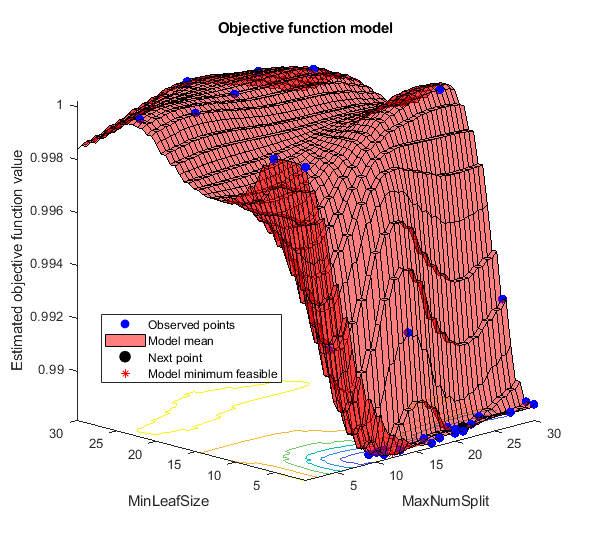

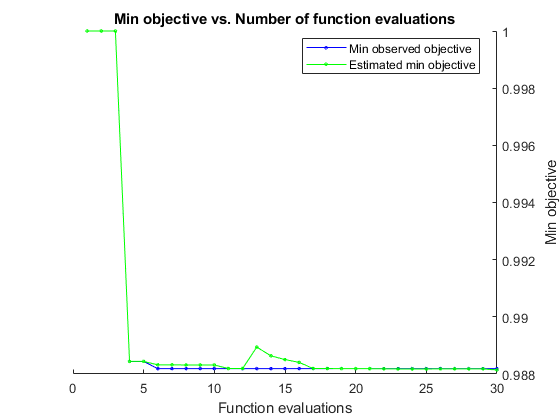


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 45.9707 seconds
Total objective function evaluation time: 27.4342

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

        13              3     

Observed objective function value = 0.98819
Estimated objective function value = 0.98823
Function evaluation time = 0.91915

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

        12              3     

Estimated objective function value = 0.98814
Estimated function evaluation time = 0.8273



% 7a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = f-beta, PCA)
% 7a-i) Define loss function
loss = @(params)fb_loss_dt_cv(params, X_train_PCA, y_train, c); % see helper function

% 7a-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

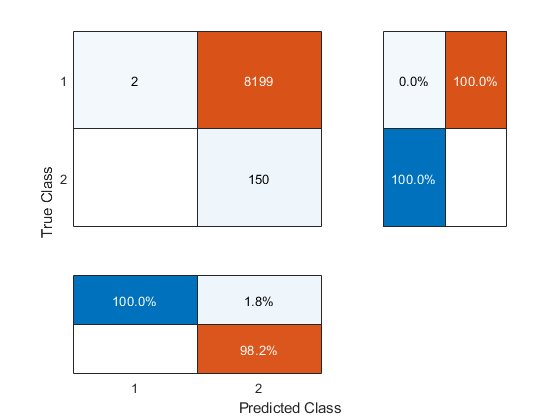

accuracy = 0.0182

precision = 0.0180

recall = 1

specificity = 2.4387e-04

fb = 0.0353


% 7a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train_PCA, y_train, 'Reproducible', 1, ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 7a-iv) Evaluate final model  on test data
test_model(dt_best, X_test_PCA, y_test)

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |    dstWeight |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |           1 |       2.682 |           1 |           1 |           18 |  correlation |        equal |
|    2 | Accept |           1 |      1.8586 |           1 |           1 |           10 |    euclidean |      inverse |
|    3 | Best   |     0.96674 |      4.0661 |     0.96674 |     0.98092 |            2 |       cosine | squaredinver |
|    4 | Accept |           1 |      2.6689 |     0.96674 |     0.96674 |           18 |    euclidean |      inverse |
|    5 | Best   |     0.96663 |      4.9726 |   

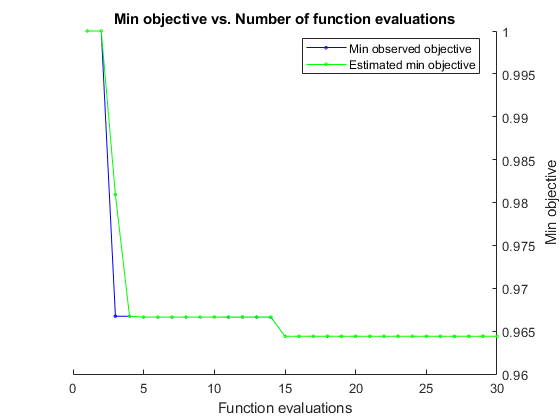


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 105.9321 seconds
Total objective function evaluation time: 91.9729

Best observed feasible point:
    n       dst         dstWeight   
    _    _________    ______________

    1    euclidean    squaredinverse

Observed objective function value = 0.9644
Estimated objective function value = 0.9644
Function evaluation time = 1.4688

Best estimated feasible point (according to models):
    n       dst         dstWeight   
    _    _________    ______________

    1    euclidean    squaredinverse

Estimated objective function value = 0.9644
Estimated function evaluation time = 1.6757



% 7b) KNN: Bayesian Optimization (CV = k-fold, loss = f-beta, PCA)
% 7b-i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train_PCA,y_train, c); % see helper function

% 7b-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.9820

precision = NaN

recall = 0

specificity = 1

fb = 0


% 7b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train_PCA, y_train, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst), ...
    'DistanceWeight',char(z.dstWeight));

% 7b-iv) Evaluate final model on test data
test_model(knn_best, X_test_PCA, y_test)

## 8) Hyperparameter Tuning Models (CV = k-fold, loss = f-beta, SMOTE + PCA)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.18567 |      1.2594 |     0.18567 |     0.18567 |            2 |           23 |
|    2 | Best   |     0.10126 |       2.269 |     0.10126 |     0.10546 |           28 |           11 |
|    3 | Accept |     0.14572 |      1.6577 |     0.10126 |     0.11802 |            7 |           21 |
|    4 | Accept |     0.10268 |      2.2798 |     0.10126 |     0.10339 |           21 |            3 |
|    5 | Accept |     0.10143 |      2.2711 |     0.10126 |     0.10126 |           25 |           24 |
|    6 | Accept |     0.12503 |      1.9545 |     0.10126 |     

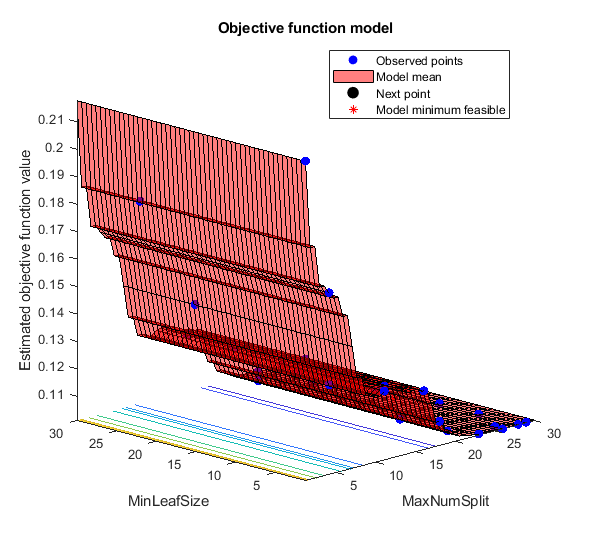

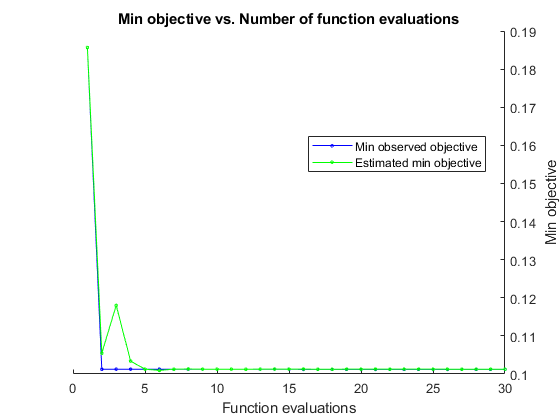


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 80.1767 seconds
Total objective function evaluation time: 63.4474

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

        26              2     

Observed objective function value = 0.10121
Estimated objective function value = 0.10126
Function evaluation time = 2.2943

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

        26              2     

Estimated objective function value = 0.10126
Estimated function evaluation time = 2.3355



% 8a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = f-beta, SMOTE + PCA)
% 8a-i) Define loss function
loss = @(params)fb_loss_dt_cv(params, X_train_SMOTE_PCA, y_train_SMOTE, c_SMOTE); % see helper function

% 8a-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

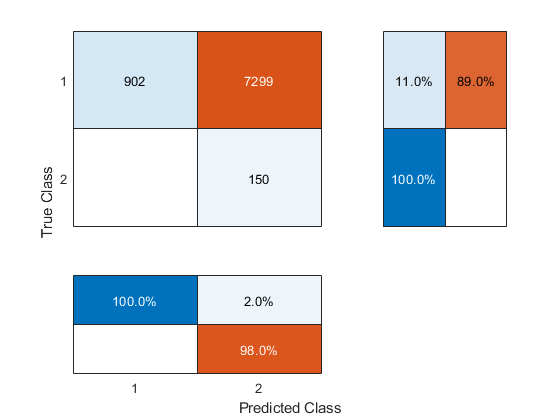

accuracy = 0.1260

precision = 0.0201

recall = 1

specificity = 0.1100

fb = 0.0395


% 8a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train_SMOTE_PCA, y_train_SMOTE, 'Reproducible', 1, ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 8a-iv) Evaluate final model on test data
test_model(dt_best, X_test_SMOTE_PCA, y_test)

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |    dstWeight |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |    0.020965 |      10.755 |    0.020965 |    0.020965 |           18 |  correlation |        equal |
|    2 | Best   |      0.0145 |      14.081 |      0.0145 |    0.014835 |           10 |    euclidean |      inverse |
|    3 | Accept |    0.015068 |      21.675 |      0.0145 |    0.014696 |            2 |       cosine | squaredinver |
|    4 | Accept |    0.017802 |      5.5483 |      0.0145 |    0.016645 |           18 |    euclidean |      inverse |
|    5 | Accept |    0.015068 |       15.42 |   

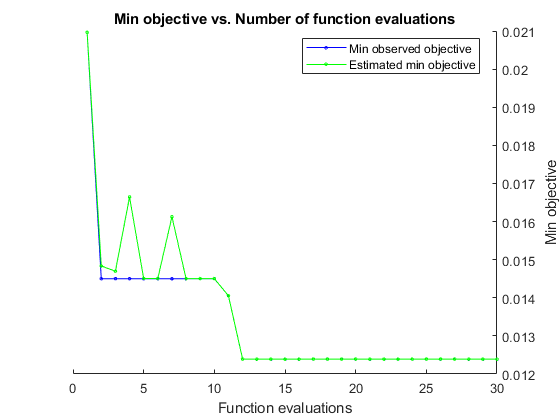


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 356.9004 seconds
Total objective function evaluation time: 329.5271

Best observed feasible point:
    n       dst       dstWeight
    _    _________    _________

    5    euclidean     inverse 

Observed objective function value = 0.01239
Estimated objective function value = 0.012391
Function evaluation time = 3.5677

Best estimated feasible point (according to models):
    n       dst       dstWeight
    _    _________    _________

    5    euclidean     inverse 

Estimated objective function value = 0.012391
Estimated function evaluation time = 4.9133



% 8b) KNN: Bayesian Optimization (CV = k-fold, loss = f-beta, SMOTE + PCA)
% 8b-i) Define loss function
loss = @(params)fb_loss_knn_cv(params, X_train_SMOTE_PCA, y_train_SMOTE, c_SMOTE); % see helper function

% 8b-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.9820

precision = NaN

recall = 0

specificity = 1

fb = 0


% 8b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train_SMOTE_PCA, y_train_SMOTE, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst), ...
    'DistanceWeight',char(z.dstWeight));

% 8b-iv) Evaluate final model on test data
test_model(knn_best, X_test_SMOTE_PCA, y_test)

## 9) Hyperparameter Tuning Model (CV = k-fold, loss = accuracy, SMOTE + PCA)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.19449 |      1.3163 |     0.19449 |     0.19449 |            2 |           23 |
|    2 | Best   |     0.10384 |      2.7518 |     0.10384 |     0.10836 |           28 |           11 |
|    3 | Accept |     0.15373 |      2.0847 |     0.10384 |     0.11675 |            7 |           21 |
|    4 | Accept |     0.10455 |      2.7668 |     0.10384 |     0.10501 |           21 |            3 |
|    5 | Accept |     0.10402 |      2.6814 |     0.10384 |     0.10386 |           25 |           24 |
|    6 | Accept |     0.12455 |      2.0803 |     0.10384 |     

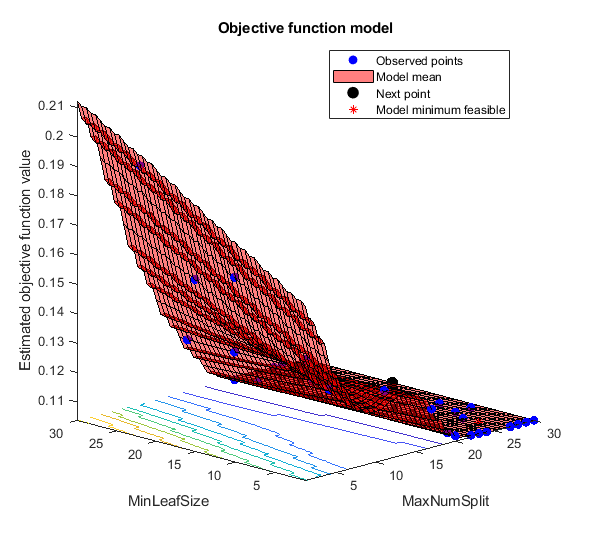

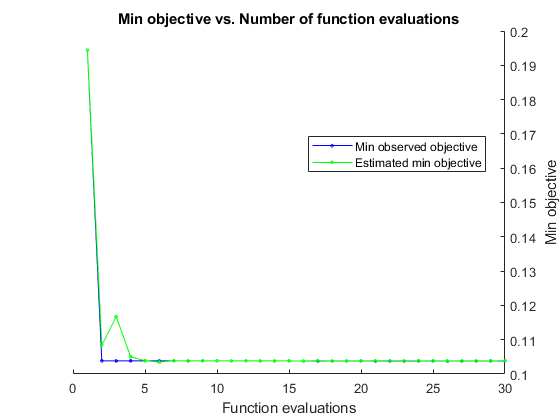


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 93.2944 seconds
Total objective function evaluation time: 71.699

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

        26              6     

Observed objective function value = 0.10378
Estimated objective function value = 0.1038
Function evaluation time = 2.6292

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

        28              1     

Estimated objective function value = 0.10385
Estimated function evaluation time = 2.5086



% 9a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = accuracy, SMOTE + PCA)
% 9a-i) Define loss function
loss = @(params)kfoldLoss(fitctree(X_train_SMOTE_PCA, y_train_SMOTE, 'CVPartition', c_SMOTE, 'Reproducible', 1,...
                                     'MaxNumSplits',params.MaxNumSplit, ...
                                     'MinLeafSize',params.MinLeafSize));
% 9a-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

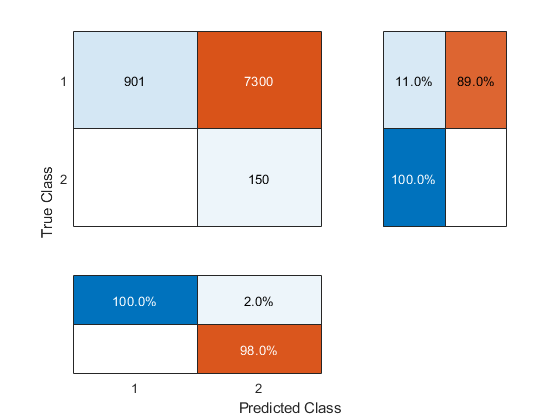

accuracy = 0.1259

precision = 0.0201

recall = 1

specificity = 0.1099

fb = 0.0395


% 9a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train_SMOTE_PCA, y_train_SMOTE, 'Reproducible', 1, ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 9a-iv) Evaluate final model on test data
test_model(dt_best, X_test_SMOTE_PCA, y_test)

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |            n |          dst |    dstWeight |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |    0.021148 |      22.475 |    0.021148 |    0.021148 |           18 |  correlation |        equal |
|    2 | Best   |    0.014524 |      10.303 |    0.014524 |    0.014852 |           10 |    euclidean |      inverse |
|    3 | Accept |    0.015101 |      15.416 |    0.014524 |    0.014724 |            2 |       cosine | squaredinver |
|    4 | Accept |    0.017897 |      3.5128 |    0.014524 |    0.016518 |           18 |    euclidean |      inverse |
|    5 | Accept |    0.015101 |      11.113 |   

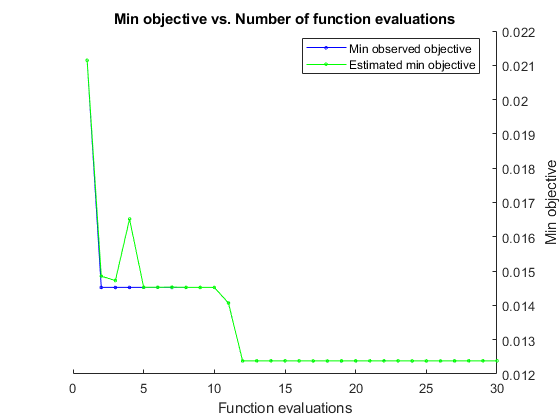


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 301.0616 seconds
Total objective function evaluation time: 277.8203

Best observed feasible point:
    n       dst       dstWeight
    _    _________    _________

    5    euclidean     inverse 

Observed objective function value = 0.012382
Estimated objective function value = 0.012384
Function evaluation time = 3.0066

Best estimated feasible point (according to models):
    n       dst       dstWeight
    _    _________    _________

    5    euclidean     inverse 

Estimated objective function value = 0.012384
Estimated function evaluation time = 4.1731



% 9b) KNN: Bayesian Optimization (CV = k-fold, loss = accuracy, SMOTE + PCA)
% 9b-i) Define loss function
loss = @(params)kfoldLoss(fitcknn(X_train_SMOTE_PCA, y_train_SMOTE, 'Standardize', 1, 'CVPartition', c_SMOTE, ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst), ...
            'DistanceWeight',char(params.dstWeight)));
% 9b-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.9820

precision = NaN

recall = 0

specificity = 1

fb = 0


% 9b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train_SMOTE_PCA, y_train_SMOTE, 'Standardize', 1, ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst), ...
    'DistanceWeight',char(z.dstWeight));

% 9b-iv) Evaluate final model on test data
test_model(knn_best, X_test_SMOTE_PCA, y_test)

function test_model(model, X_test, y_test)
    y_pred = predict(model, X_test);
    cmat = confusionmat(y_test, y_pred);  % Confusion matrix
    cm = confusionchart(cmat);
    cm.RowSummary = 'row-normalized';
    cm.ColumnSummary = 'column-normalized';
    [accuracy, precision, recall, specificity, fb] = binary_eval_metrics(y_test, y_pred) 
end

% Decision tree loss loss function CV
function fb = fb_loss_dt_cv(params, X_train, y_train, cv_part)
        % Train model with selected parameters
        model = fitctree(X_train, y_train, 'CVPartition', cv_part, 'Reproducible', 1,...
             'MaxNumSplits',params.MaxNumSplit, ...
             'MinLeafSize',params.MinLeafSize);
               
        % Calculate F1 score
        y_pred = kfoldPredict(model);
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end

% KNN function CV
function fb = fb_loss_knn_cv(params, X_train, y_train, cv_part)
        model = fitcknn(X_train, y_train, 'Standardize', 1, 'CVPartition', cv_part, ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst), ...
            'DistanceWeight',char(params.dstWeight));
        
        % Calculate F-beta score
        y_pred = kfoldPredict(model);   
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end

% Evaluation metrics for binary classification
function [acc, prec, rec, spec, fb] = binary_eval_metrics(y_test, y_pred)
    cmat = confusionmat(y_test, y_pred);
    tn = cmat(1,1);
    fn = cmat(2,1);
    tp = cmat(2,2);
    fp = cmat(1,2);

    % Statistics of interest for confusion matrix
    b = 1; % beta < 1 favours precision over recall.
    prec = tp / (tp + fp); % precision
    rec = tp / (tp + fn); % recall
    spec = tn / (tn + fp); % specificity
    acc = (tp + tn) / (tn + fn + tp + fp);
    fb = ((1+b^2)*tp) / ((1+b^2)*tp + b^2 * fp + fn); % (see https://en.wikipedia.org/wiki/F-score)
end
%#ok<*ASGLU,*NOPRT> 